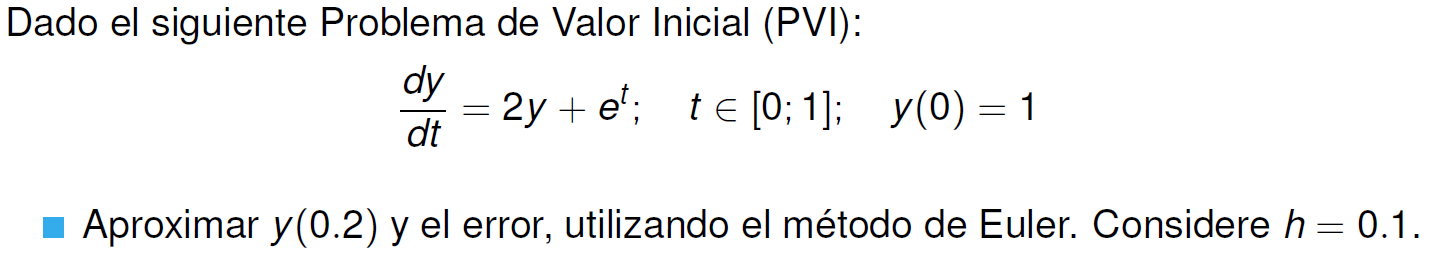

% Definición de la EDO
f = @(t, y) 2*y + exp(t);

% Parámetros
a = 0; % tiempo inicial
b = 1; % tiempo final
y0 = 1; % condición inicial
h = 0.1; % tamaño del paso

% Solución Analítica
syms y(t)
ode = diff(y, t) == 2*y + exp(t);
cond = y(0) == 1;
ySol(t) = dsolve(ode, cond);

% Aproximación numérica con Método de Euler
result_euler = euler(f, a, b, y0, h);

% Aproximación numérica con Método de Heun (RK2)
result_rk2_heun = rk2(f, a, b, y0, h);

% Aproximación numérica con Método de Runge-Kutta de Orden 4 (RK4)
result_rk4 = rk4(f, a, b, y0, h);

% Aproximar y(0.2)
t_target = 0.2;

% Método de Euler
index_euler = find(abs(result_euler(:, 2) - t_target) < 1e-10);
y_euler = result_euler(index_euler, 3);

% Método de Heun (RK2)
index_rk2 = find(abs(result_rk2_heun(:, 2) - t_target) < 1e-10);
y_rk2 = result_rk2_heun(index_rk2, 3);

% Método de Runge-Kutta de Orden 4 (RK4)
index_rk4 = find(abs(result_rk4(:, 2) - t_target) < 1e-10);
y_rk4 = result_rk4(index_rk4, 3);

% Valor exacto de y(0.2) usando la solución analítica
y_exact = double(ySol(t_target));

% Cálculo de errores
error_euler = abs(y_euler - y_exact);
error_rk2 = abs(y_rk2 - y_exact);
error_rk4 = abs(y_rk4 - y_exact);

fprintf('Aproximación de y(0.2) usando el Método de Euler: %f\n', y_euler);

Aproximación de y(0.2) usando el Método de Euler: 1.670517


fprintf('Error con el Método de Euler: %f\n', error_euler);

Error con el Método de Euler: 0.091730



fprintf('Aproximación de y(0.2) usando el Método de Heun (RK2): %f\n', y_rk2);

Aproximación de y(0.2) usando el Método de Heun (RK2): 1.756396


fprintf('Error con el Método de Heun (RK2): %f\n', error_rk2);

Error con el Método de Heun (RK2): 0.005851



fprintf('Aproximación de y(0.2) usando el Método de Runge-Kutta de Orden 4: %f\n', y_rk4);

Aproximación de y(0.2) usando el Método de Runge-Kutta de Orden 4: 1.762235


fprintf('Error con el Método de Runge-Kutta de Orden 4: %f\n', error_rk4);

Error con el Método de Runge-Kutta de Orden 4: 0.000012


function z = euler(f, a, b, y0, h)
    % f: función que representa la EDO (dy/dt = f(t, y))
    % a: tiempo inicial
    % b: tiempo final
    % y0: condición inicial
    % h: tamaño del paso

    N = floor((b - a) / h); % número de pasos
    y = zeros(1, N+1); % preasignar vector y
    y(1) = y0; % condición inicial
    z = zeros(N+1, 4); % preasignar matriz de salida

    t = a; % inicializar tiempo
    for i = 1:N
        % Calcular la pendiente k1
        k1 = f(t, y(i));

        % Actualizar valor de y
        y(i+1) = y(i) + h * k1;

        % Almacenar los resultados en z
        z(i, :) = [i-1, t, y(i), k1];

        % Actualizar el tiempo
        t = t + h;
    end

    % Añadir el punto final a z
    z(N+1, :) = [N, t, y(end), NaN];
end

function z = rk2(f, a, b, y0, h)
    % f: función que representa la EDO (dy/dt = f(t, y))
    % a: tiempo inicial
    % b: tiempo final
    % y0: condición inicial
    % h: tamaño del paso

    N = floor((b - a) / h); % número de pasos
    y = zeros(1, N+1); % preasignar vector y
    y(1) = y0; % condición inicial
    z = zeros(N+1, 6); % preasignar matriz de salida

    t = a; % inicializar tiempo
    for i = 1:N
        % Calcular pendientes k
        k1 = f(t, y(i));
        k2 = f(t + h, y(i) + k1*h);

        % Actualizar valor de y
        y(i+1) = y(i) + (h/2) * (k1 + k2);

        % Almacenar los resultados en z
        z(i, :) = [i-1, t, y(i), k1, k2, y(i+1)];

        % Actualizar el tiempo
        t = t + h;
    end

    % Añadir el punto final a z
    z(N+1, :) = [N, t, y(end), NaN, NaN, NaN];
end

function z = rk4(f, a, b, y0, h)
    % f: función que representa la EDO (dy/dt = f(t, y))
    % a: tiempo inicial
    % b: tiempo final
    % y0: condición inicial
    % h: tamaño del paso

    N = floor((b - a) / h); % número de pasos
    y = zeros(1, N+1); % preasignar vector y
    y(1) = y0; % condición inicial
    z = zeros(N+1, 8); % preasignar matriz de salida

    t = a; % inicializar tiempo
    for i = 1:N
        % Calcular pendientes k
        k1 = f(t, y(i));
        k2 = f(t + h/2, y(i) + k1*h/2);
        k3 = f(t + h/2, y(i) + k2*h/2);
        k4 = f(t + h, y(i) + k3*h);

        % Actualizar valor de y
        y(i+1) = y(i) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);

        % Almacenar los resultados en z
        z(i, :) = [i-1, t, y(i), k1, k2, k3, k4, y(i+1)];

        % Actualizar el tiempo
        t = t + h;
    end

    % Añadir el punto final a z
    z(N+1, :) = [N, t, y(end), NaN, NaN, NaN, NaN, NaN];
end